# 第三次作业

## 车轮轨迹

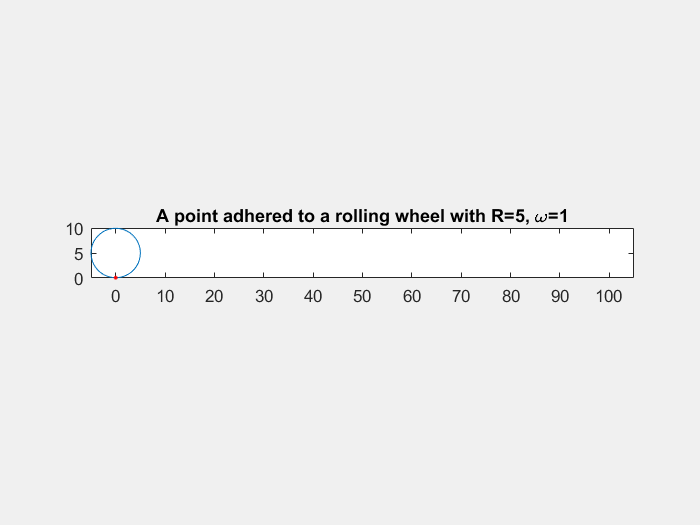

R=5;omega=1;v=omega*R;Phi=0:0.1:2*pi+.1;T=0:0.1:20;
x=@(t,phi)v*t-R*sin(omega*t+phi);y=@(t,phi)R*(1-cos(omega*t+phi));
figure('visible','on'); % Since Live Script hasn't added the feature of animations, we have to force the window to pop out here.

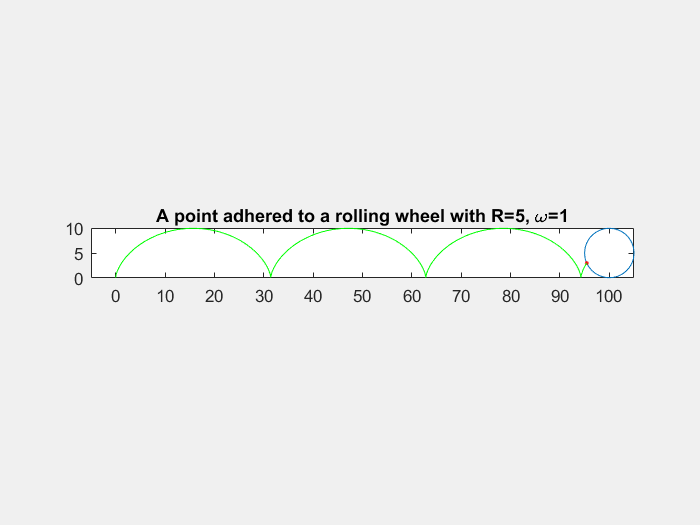

for i=1:201
    plot(x(T(i),Phi),y(T(i),Phi));hold on; % 车轮
    plot(x(T(i),0),y(T(i),0),'r.'); % 标记点
    plot(x(T(1:i),0),y(T(1:i),0),'g-'); % 轨迹
    axis equal;axis([-5,105,0,10]);
    hold off;
    title('A point adhered to a rolling wheel with R=5, \omega=1')
    drawnow; % or use "getframe".
end

## 1.14 Lissajous图

频率比为有理数的闭合，无理数的不闭合而充满整个单位方形。如$\pi\approx\frac{22}{7}$，开始时轨迹很接近，但长时间运行就有明显区别。

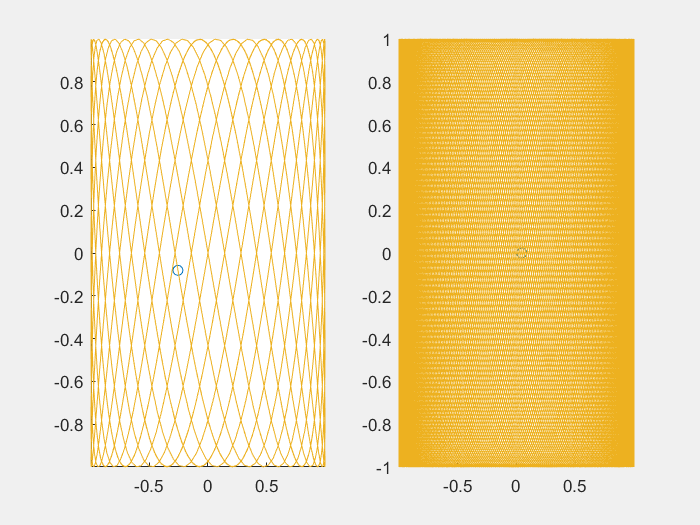

t=0:0.05:600;
x=sin(t);
y1=sin(22/7*t(1:1200));y2=sin(pi*t);
figure('visible','on');
    subplot(1,2,1);comet(x(1:1200),y1);
    subplot(1,2,2);comet(x,y2);
% saveas(gcf,'Lissajous.pdf')

## 1.16 3D轨迹

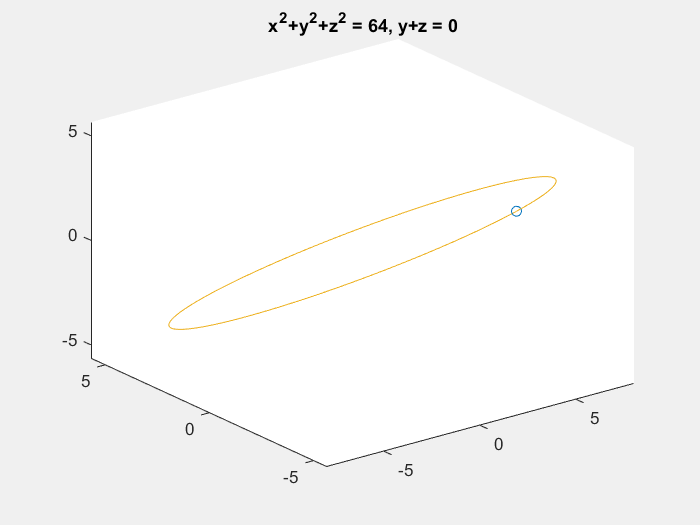

t=0:0.01:2*pi;
figure('visible','on');
    [x,y,z]=deal(8*cos(t),4*2^.5*sin(t),-4*2^.5*sin(t));
    comet3(x,y,z);
    title('x^2+y^2+z^2 = 64, y+z = 0');
% saveas(gcf,'comet3D.pdf')

## 1.19 ezsurf曲面

（尽管都会提示用fsurf instead既然题目一定要用ezsurf那也只好这样了。）

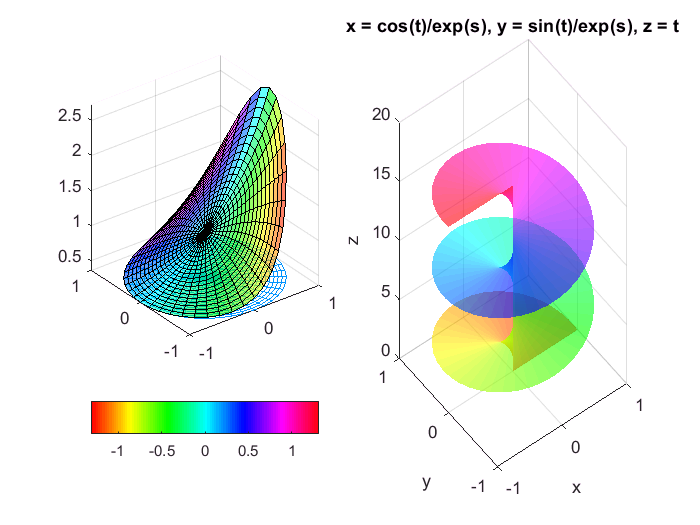

x=@(s,t)cos(t)./exp(s);
y=@(s,t)sin(t)./exp(s);
z=@(s,t)t;
ezsurf(x,y,z,[0,8,0,5*pi],100);
colormap(hsv(100));shading interp;feval('alpha',0.6);
% saveas(gcf,'ezsurf.pdf')

## 1.20 椭球与抛物柱面

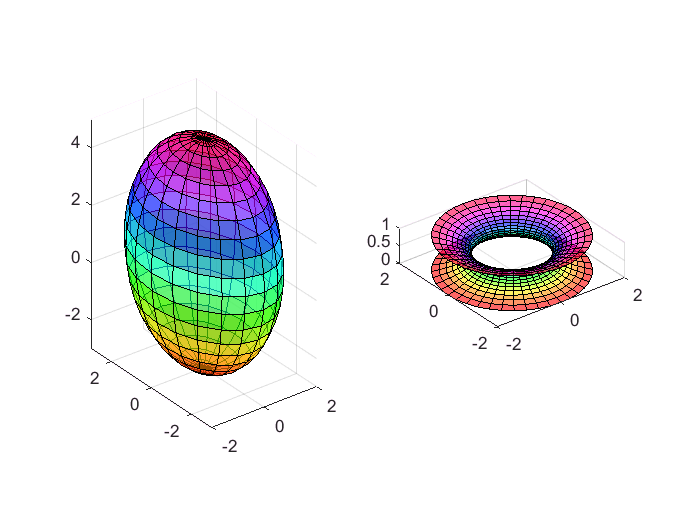

subplot(1,2,1);
ellipsoid(0,0,1,2,3,4);axis equal;feval('alpha',0.6);shading faceted;
subplot(1,2,2);
t=-1:0.1:1;
cylinder(1+t.^2,40);axis equal;feval('alpha',0.6);shading faceted;
colormap(hsv(100));
% saveas(gcf,'ec.pdf')

## 1.22 复变函数图形

注意$z^{0.2}$是一个五叶曲面。

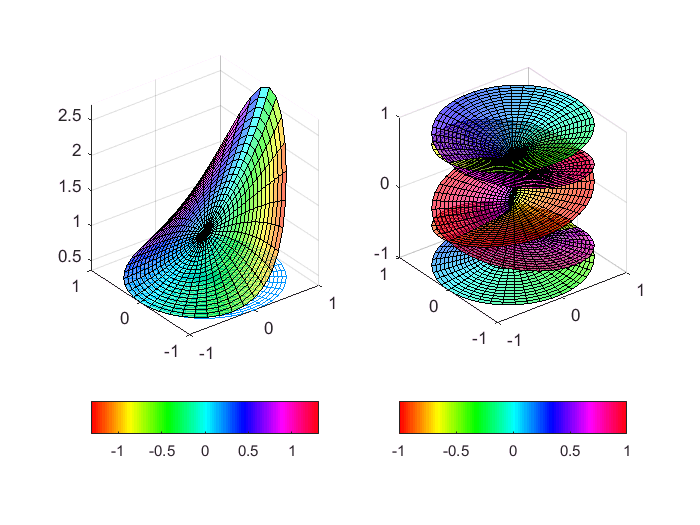

subplot(1,2,1)
    u=cplxgrid(20);
    cplxmap(u,exp(u))
    colorbar('southoutside')
    axis equal;feval('alpha',0.6);shading faceted;
    colormap(hsv(100));
subplot(1,2,2);
    cplxroot(5);
    colorbar('southoutside');
    axis equal;feval('alpha',0.6);shading faceted;
    colormap(hsv(100));
% saveas(gcf,'cplxfg.pdf')

## 1.23 弦振动本征函数图形

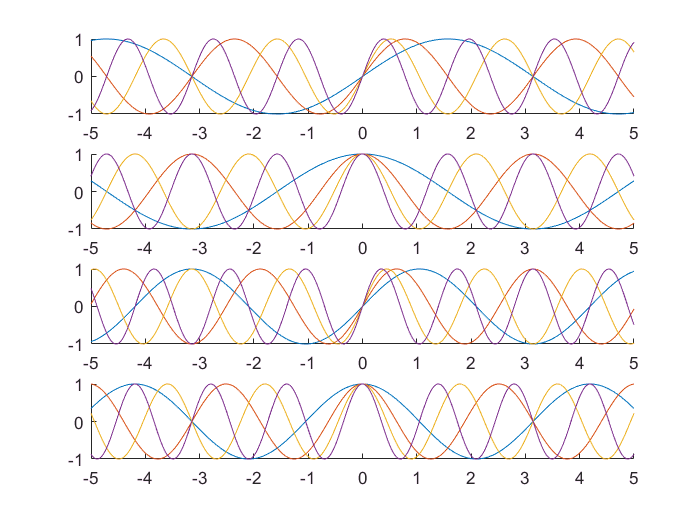

E = { }; l = pi; a = 10;
tscale = 0:0.2:5; xscale = -5:0.01:5;
bottom = meshgrid(xscale, tscale); syms xscale t n x;
timefac = cos(n*pi*a.*t./l); T = subs(timefac,t,tscale);
for k = 1:4
    [e1 e2 e3 e4] = deal(sin((k*pi.*x)./l), cos((k*pi.*x)./l), sin(((k+.5)*pi.*x)./l), cos(((k+.5)*pi.*x)./l));
    E{k} = {e1 e2 e3 e4};
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
    for i=1:4
        subplot(4,1,i)
        hold on
        for j=1:4
            xscale=-5:0.01:5;
            plot(xscale,vpa(subs(E{j}(i),x,xscale)));
        end
        hold off;
    end

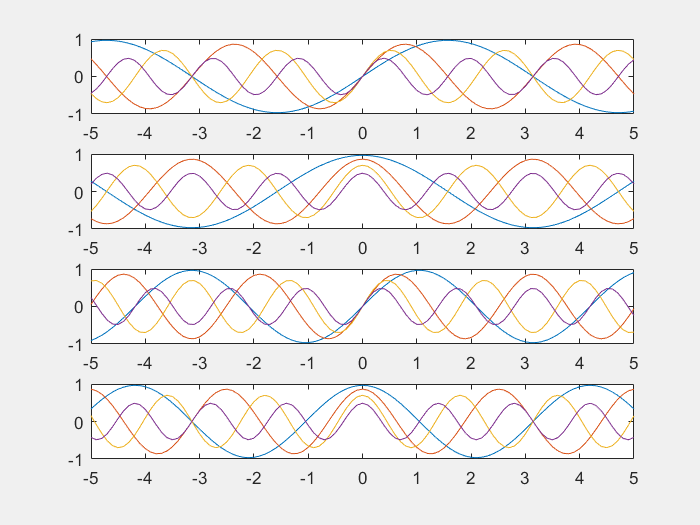

% saveas(gcf,'eigenfuns.pdf')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure('visible', 'on');
for k=1:26
    for i=1:4
        subplot(4,1,i);
        hold off;
        for j=1:4
            xscale=-5:0.1:5;
            ydat=vpa(subs(E{j}(i),x,xscale)).*vpa(subs(T(k),n,j));
            plot(xscale,ydat);axis([-5 5 -1 1]);
            hold on;
        end
    end
    getframe;
end

drawnow;
% saveas(gcf,'standingWaves.fig');

如果要保存avi视频，可以改为：

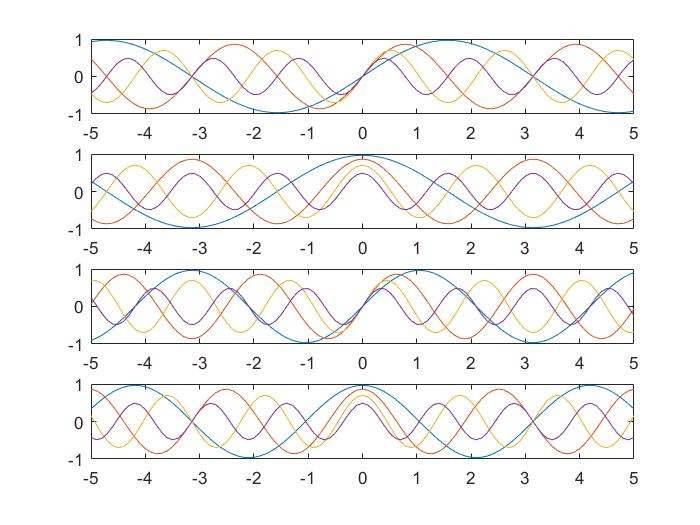

E = { }; l = pi; a = 10;
tscale = 0:0.2:5; xscale = -5:0.01:5;
bottom = meshgrid(xscale, tscale); syms xscale t n x;
timefac = cos(n*pi*a.*t./l); T = subs(timefac,t,tscale);
for k = 1:4
    [e1 e2 e3 e4] = deal(sin((k*pi.*x)./l), cos((k*pi.*x)./l), sin(((k+.5)*pi.*x)./l), cos(((k+.5)*pi.*x)./l));
    E{k} = {e1 e2 e3 e4};
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
    fps = 3; % Set frames per second.
    m=moviein(26);
    for k=1:26
        for i=1:4
            subplot(4,1,i);
            hold off;
            for j=1:4
                xscale = -5:0.1:5;
                ydat = vpa(subs(E{j}(i), x, xscale)).*vpa(subs(T(k), n, j));
                plot(xscale, ydat); axis([-5 5 -1 1]);
                hold on;
            end
        end
        m(:, k) = getframe;
    end

delete eigenfun_test.avi % Matlab sometimes gives a warning on generating v if the video already exists.
v = VideoWriter('eigenfun_test.avi');
open(v); writeVideo(v, m); close(v);

## 1.26 牛顿环干涉图样

光强$I=I_1+I_2+2\sqrt{I_1I_2}\cos{\Delta \phi}=2I_1(1+\cos{\Delta \phi})=2I_1\sin^2(\Delta \phi/2)=2I_1\sin^2[\pi/\lambda(2d+\lambda/2)]\approx2I_1\sin^2[2\pi d/\lambda]\approx 2I_1\sin^2[\pi r^2/\lambda R]$（远场近轴短波长）

这样近似就必须使距离$r\gg R$（半径）。

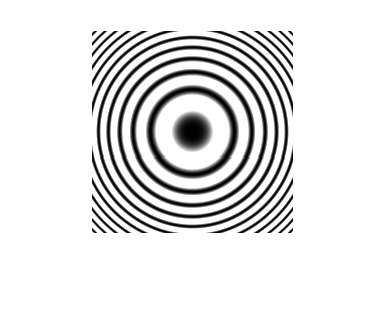

R=30;I1=1;lambda=5.893e-7;
x=-.01:0.0001:.01;y=-.01:0.0001:.01;
[X,Y]=meshgrid(x,y);
I=2*I1*sin(pi*(X.^2+Y.^2)/(lambda*R)).^2;
imshow(I)

极坐标的画法举例：用surf函数画成曲面，默认是从上往下看的，画成透明的就可以看到坐标网格了。

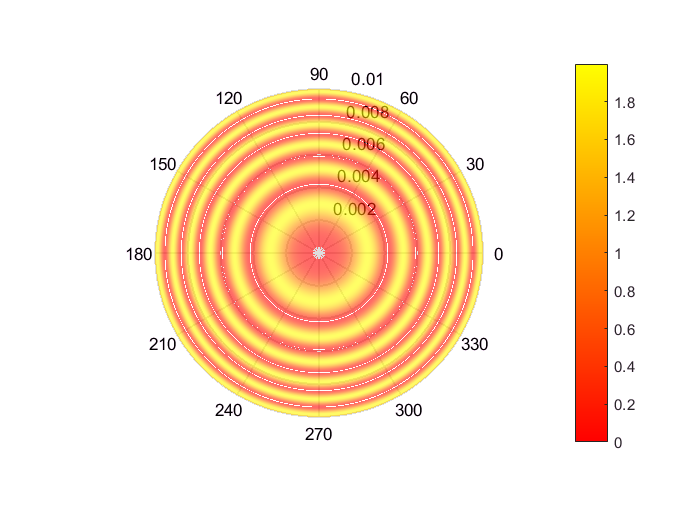

clear all;
R=30;I1=1;lambda=5.893e-7;
r=0:0.0001:0.01;t=0:0.001:2*pi+.1;
[theta,rho]=meshgrid(t,r);
[x,y]=pol2cart(theta,rho);z=x+i*y;
I=2*I1*sin(pi*abs(z).^2/(lambda*R)).^2;
figure;
templine=polar([0 2*pi], [0 0.01]);delete(templine);
hold on;
surf(x,y,I);shading interp;axis equal;view([0 0 100]);
colormap(autumn(500));colorbar;feval('alpha',0.6);
hold off;
% saveas(gcf,'newtonsRings.pdf');

也可以从外往里用fill画同心圆

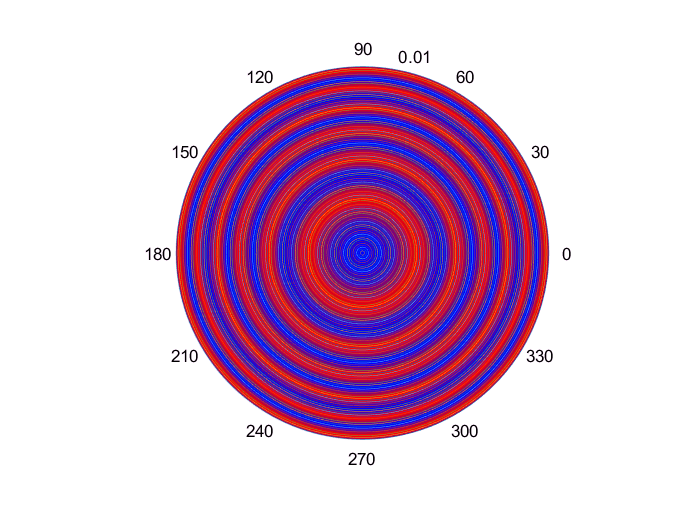

R=30;I1=1;lambda=5.893e-7;
r=0:0.0001:.01;
I=2*I1*sin(pi*(r.^2)/(lambda*R)).^2;
i=I./max(I);
theta=linspace(0,2*pi,360);
figure;
for k=1:length(r)
    h=polar(theta,r(length(r)-k+1)*ones([1,length(theta)]));hold on;
    fill(h.XData,h.YData,[i(length(r)-k+1),0,1-i(length(r)-k+1)],'EdgeColor','none');
end

## 切片电偶极子电势

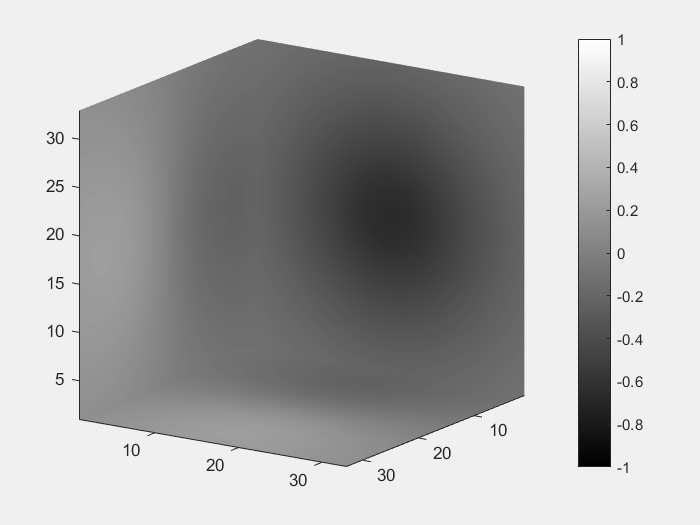

x=-0.8:.05:0.8;y=x;z=x;
t=linspace(1,32,100);
[X,Y,Z]=meshgrid(x,y,z);
V=1./sqrt((X-0.2).^2+Y.^2+Z.^2)-1./sqrt((X+0.2).^2+Y.^2+Z.^2);
v=(V-min(min(min(V))))./(max(max(max(V)))-min(min(min(V))));
figure('visible','on');

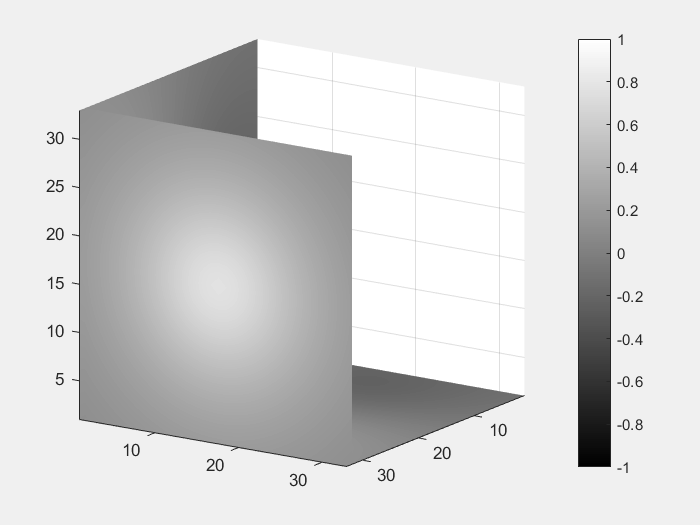

for i=1:100
    slice(V,t(i),1,1);shading interp;axis equal;caxis([-1,1]);colormap gray(200);colorbar;view([3,2,1]);
    drawnow;
end

## 其它要求

- 课本例题

- 指令总结

- 动画总结PPT

# 链接

- [下载此页对应的实时脚本](https://wang-guosheng.github.io/CompPhyExs/ex3.mlx)

- [下载此页对应的PDF](https://wang-guosheng.github.io/CompPhyExs/ex3.pdf)

- [驻波程序输出视频](https://wang-guosheng.github.io/CompPhyExs/eigenfun_test.avi)

- [主页](https://wang-guosheng.github.io/CompPhyExs/main.html)

- [下一页](https://wang-guosheng.github.io/CompPhyExs/ex4.html)